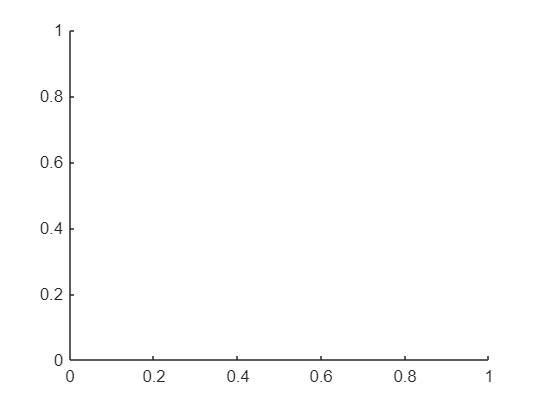

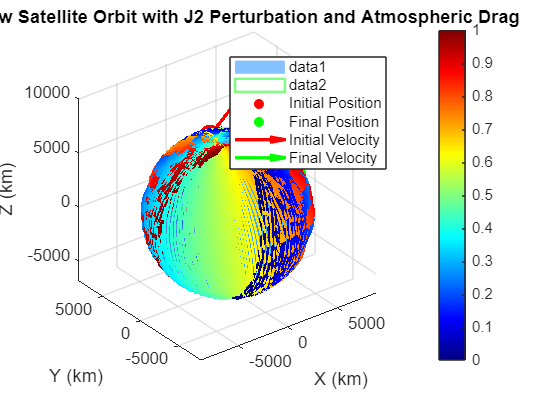

%MAE 180 PROJ S-3 TEAM CODE

clc
clear
format long

%% Common parameters for both runs
lat = 32.8811913;    % Site latitude (phi) in degrees
alt = 111E-3;        % Site altitude in km
JD_prop = 2460542.7792; % Propagation Julian Date (second value given on file)

%% First Run: Group S-3 (ADVENTURE 1)
% Days (JD), right ascension (ra), declination (dec), and local sidereal time (lst)
JD  = [2460262.842373029;
       2460262.842893863;
       2460262.843414696];
   
ra  = [135.514066681081;
       148.057402685433;
       165.762330451468];

dec = [29.155447177193;
       45.578290874916;
       56.881276513171];

lst = [59.199692009582;
       59.387705356210;
       59.575718703254];

% Calculate orbit parameters for Group S-3
[r0, v0, oe0, r, v, oe] = OrbitComp(lat, lst, alt, ra, dec, JD, JD_prop);


% Display Results
fprintf('\nInitial State: r0 = [%f, %f, %f] km, v0 = [%f, %f, %f] km/s\n', r0, v0);


Initial State: r0 = [2098.703281, 5002.055406, 4219.021380] km, v0 = [-0.600570, -4.751516, 5.924891] km/s


fprintf('Initial Elements: a = %f km, e = %f, i = %f deg, Ω = %f deg, ω = %f deg, M = %f deg\n', oe0);

Initial Elements: a = 6876.674826 km, e = 0.000889, i = 97.648203 deg, Ω = 73.233711 deg, ω = 79.313800 deg, M = 319.028911 deg


fprintf('\nPropagated State: r = [%f, %f, %f] km, v = [%f, %f, %f] km/s\n', r, v);


Propagated State: r = [6755.295543, -245.860903, 1253.781484] km, v = [-1.418605, -0.979080, 7.415512] km/s


fprintf('Propagated Elements: a = %f km, e = %f, i = %f deg, Ω = %f deg, ω = %f deg, M = %f deg\n', oe);

Propagated Elements: a = 6873.056156 km, e = 0.000907, i = 97.644505 deg, Ω = 359.342125 deg, ω = 119.396107 deg, M = 251.305232 deg
